1. 绘制DH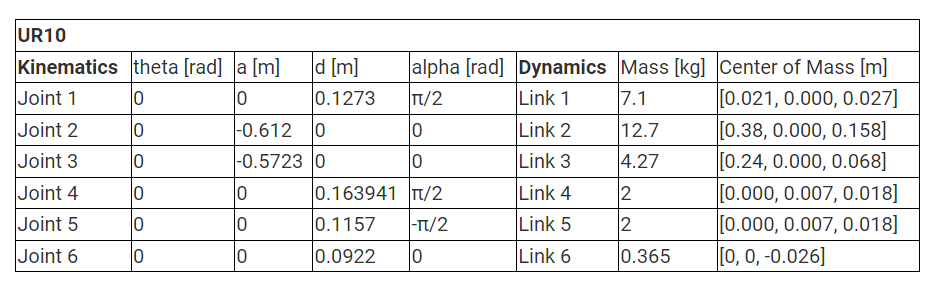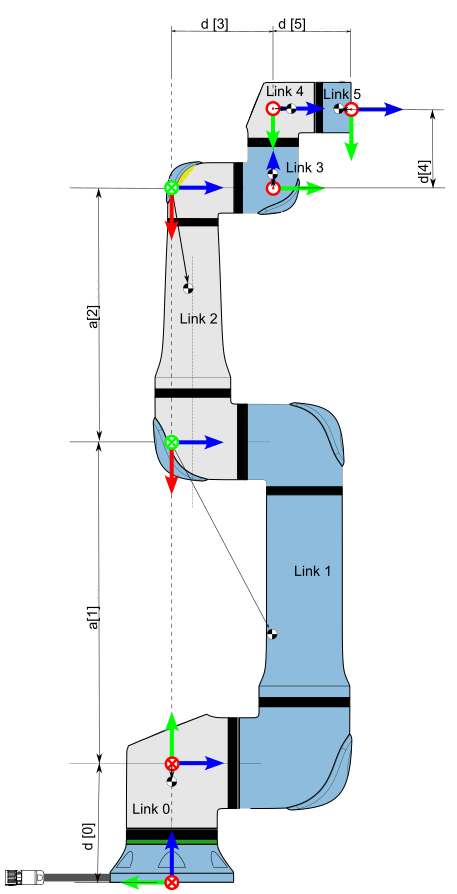

clear,clf

L1 = 128/1000;
L2 = 163.9/1000;
L3 = 612.7/1000;
L4 = 92.2/1000;
L5 = 687.3/1000;
L7 = 150/1000;
L8 = L3/2;
L9 = 10/1000;
L10 = L5/2;
L11 = 115.7/1000;

[q1, q2, q3, q4, q5, q6] = deal(0, 0, 0, 0, 0, 0);

% 官网
% DH = [q1,       L1,         0,          pi/2;
%       q2-pi/2,  0,          -L3,        0;
%       q3,       0,          -(L5-L11),  0;
%       q4-pi/2,  L2,         0,          pi/2;
%       q5+pi,    L11,        0,          -pi/2;
%       q6,       L4,         0,          0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % 我的
% DH = [q1,       L1,         0,          -pi/2;
%       q2-pi/2,  L7,         L3,         pi;
%       -q3,      L7,         L5-L11,     pi;
%       q4-pi/2,  L2,         0,          -pi/2;
%       q5+pi,    L11,        0,          -pi/2;
%       q6,       L4,         0,          0];
% 
% DH_cm = [q1,       L1,         0,          0;
%          q2-pi/2,  L7,         L8,         0;
%          -q3,      L7+L9-L2/2, L10,        0;
%          q4,       L2,         0,          0;
%          q5,       L11,        0,         0;
%          q6,       L4,         0,        0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 尝试
DH = [q1,       L1,         0,          pi/2;
      q2,       0,          -L3,        0;
      q3,       0,          -L5,        0;
      q4,       L2,         0,          pi/2;
      q5,       L11,        0,          -pi/2;
      q6,       L4,         0,          0];

% DH_cm = [q1,       L1,         0,          0;
%          q2-pi/2,  L7,         L8,         0;
%          -q3,      L7+L9-L2/2, L10,        0;
%          q4,       L2,         0,          0;
%          q5,       L11,        0,         0;
%          q6,       L4,         0,        0];
Center_of_Mass = [[0.021,   0.0,    0.027];
                  [0.38,    0.0,    0.158];
                  [0.24,    0.0,    0.068];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.0,    -0.026]];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% O
T1_0 = relativeTrans(DH(1,:));
T2_1 = relativeTrans(DH(2,:));		
T3_2 = relativeTrans(DH(3,:));
T4_3 = relativeTrans(DH(4,:));
T5_4 = relativeTrans(DH(5,:));		
T6_5 = relativeTrans(DH(6,:));

T2_0 = T1_0 * T2_1;
T3_0 = T2_0 * T3_2;
T4_0 = T3_0 * T4_3;
T5_0 = T4_0 * T5_4;
T6_0 = T5_0 * T6_5;

% CM
Tcm1_0 = T1_0;
Tcm2_1 = T2_1;		
Tcm3_2 = T3_2;
Tcm4_3 = T4_3;
Tcm5_4 = T5_4;		
Tcm6_5 = T6_5;
Tcm1_0(1:3,4) = Center_of_Mass(1,:)';
Tcm2_1(1:3,4) = Center_of_Mass(2,:)';
Tcm3_2(1:3,4) = Center_of_Mass(3,:)';
Tcm4_3(1:3,4) = Center_of_Mass(4,:)';
Tcm5_4(1:3,4) = Center_of_Mass(5,:)';
Tcm6_5(1:3,4) = Center_of_Mass(6,:)';

Tcm2_0 = T1_0 * Tcm2_1;
Tcm3_0 = T2_0 * Tcm3_2;
Tcm4_0 = T3_0 * Tcm4_3;
Tcm5_0 = T4_0 * Tcm5_4;
Tcm6_0 = T5_0 * Tcm6_5;

Transformation_structure(:,:,1) = T1_0;
Transformation_structure(:,:,2) = T2_0;
Transformation_structure(:,:,3) = T3_0;
Transformation_structure(:,:,4) = T4_0;
Transformation_structure(:,:,5) = T5_0;
Transformation_structure(:,:,6) = T6_0;
plotter(Transformation_structure);

Transformation_cm(:,:,1) = Tcm1_0;
Transformation_cm(:,:,2) = Tcm2_0;
Transformation_cm(:,:,3) = Tcm3_0;
Transformation_cm(:,:,4) = Tcm4_0;
Transformation_cm(:,:,5) = Tcm5_0;
Transformation_cm(:,:,6) = Tcm6_0;
plotter_cm(Transformation_cm, true);

view(-90, 20)
daspect([1 1 1])

xlabel('X');
ylabel('Y');
zlabel('Z');
% xlim([-200 200]/1000)
% ylim([-200 400]/1000)
% zlim([-200 1600]/1000)


2. Transformation Matrix

clear,clf
syms q1 q2 q3 q4 q5 q6 L1 L2 L3 L4 L5 L6 L7 L8 L9 L10 L11 real

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 我的
% DH = [q1,       L1,         0,          -pi/2;
%       q2-pi/2,  L7,         L3,         pi;
%       -q3,      L7,         L5-L11,     pi;
%       q4-pi/2,  L2,         0,          -pi/2;
%       q5+pi,    L11,        0,          -pi/2;
%       q6,       L4,         0,          0];
% 
% DH_cm = [q1,       L1,         0,          0;
%          q2-pi/2,  L7,         L8,         0;
%          -q3,      L7+L9-L2/2, L10,        0;
%          q4,       L2,         0,          0;
%          q5,       L11,        0,         0;
%          q6,       L4,         0,        0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 官网
DH = [q1,       L1,         0,          pi/2;
      q2,       0,          -L3,        0;
      q3,       0,          -L5,        0;
      q4,       L2,         0,          pi/2;
      q5,       L11,        0,          -pi/2;
      q6,       L4,         0,          0];

% DH_cm = [q1,       L1,         0,          0;
%          q2-pi/2,  L7,         L8,         0;
%          -q3,      L7+L9-L2/2, L10,        0;
%          q4,       L2,         0,          0;
%          q5,       L11,        0,         0;
%          q6,       L4,         0,        0];
Center_of_Mass = [[0.021,   0.0,    0.027];
                  [0.38,    0.0,    0.158];
                  [0.24,    0.0,    0.068];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.0,    -0.026]];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 尝试
DH = [q1,       L1,         0,          pi/2;
      q2,       0,          -L3,        0;
      q3,       0,          -L5,        0;
      q4,       L2,         0,          pi/2;
      q5,       L11,        0,          -pi/2;
      q6,       L4,         0,          0];

Center_of_Mass = [[0.021,   0.0,    0.027];
                  [0.38,    0.0,    0.158];
                  [0.24,    0.0,    0.068];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.007,  0.018];
                  [0.0,     0.0,    -0.026]];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% O
T1_0 = relativeTrans(DH(1,:));
T2_1 = relativeTrans(DH(2,:));		
T3_2 = relativeTrans(DH(3,:));
T4_3 = relativeTrans(DH(4,:));
T5_4 = relativeTrans(DH(5,:));		
T6_5 = relativeTrans(DH(6,:));

T2_0 = T1_0 * T2_1;
T3_0 = T2_0 * T3_2;
T4_0 = T3_0 * T4_3;
T5_0 = T4_0 * T5_4;
T6_0 = T5_0 * T6_5;

% CM
Tcm1_0 = T1_0;
Tcm2_1 = T2_1;		
Tcm3_2 = T3_2;
Tcm4_3 = T4_3;
Tcm5_4 = T5_4;		
Tcm6_5 = T6_5;
Tcm1_0(1:3,4) = Center_of_Mass(1,:)';
Tcm2_1(1:3,4) = Center_of_Mass(2,:)';
Tcm3_2(1:3,4) = Center_of_Mass(3,:)';
Tcm4_3(1:3,4) = Center_of_Mass(4,:)';
Tcm5_4(1:3,4) = Center_of_Mass(5,:)';
Tcm6_5(1:3,4) = Center_of_Mass(6,:)';

Tcm2_0 = T1_0 * Tcm2_1;
Tcm3_0 = T2_0 * Tcm3_2;
Tcm4_0 = T3_0 * Tcm4_3;
Tcm5_0 = T4_0 * Tcm5_4;
Tcm6_0 = T5_0 * Tcm6_5;

3. Jacobian

t1_0 = T1_0(1:3, 4);
t2_0 = T2_0(1:3, 4);
t3_0 = T3_0(1:3, 4);
t4_0 = T4_0(1:3, 4);
t5_0 = T5_0(1:3, 4);
t6_0 = T6_0(1:3, 4); % {ee}
tcm1_0 = Tcm1_0(1:3, 4);
tcm2_0 = Tcm2_0(1:3, 4);
tcm3_0 = Tcm3_0(1:3, 4);
tcm4_0 = Tcm4_0(1:3, 4);
tcm5_0 = Tcm5_0(1:3, 4);
tcm6_0 = Tcm6_0(1:3, 4);

Z0 = [0 0 1]';
Z1 = T1_0(1:3,1:3) * Z0;
Z2 = T2_0(1:3,1:3) * Z0;
Z3 = T3_0(1:3,1:3) * Z0;
Z4 = T4_0(1:3,1:3) * Z0;
Z5 = T5_0(1:3,1:3) * Z0;


Jcm1 = simplify([cross(Z0, tcm1_0), [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]']);
Jcm2 = simplify([cross(Z0, tcm2_0), cross(Z1, tcm2_0-t1_0), [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, Z1, [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]']);
Jcm3 = simplify([cross(Z0, tcm3_0), cross(Z1, tcm3_0-t1_0), cross(Z2, tcm3_0-t2_0), [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, Z1, Z2, [0 0 0]', [0 0 0]', [0 0 0]']);
Jcm4 = simplify([cross(Z0, tcm4_0), cross(Z1, tcm4_0-t1_0), cross(Z2, tcm4_0-t2_0), cross(Z3, tcm4_0-t3_0), [0 0 0]', [0 0 0]'; ...
                Z0, Z1, Z2, Z3, [0 0 0]', [0 0 0]']);
Jcm5 = simplify([cross(Z0, tcm5_0), cross(Z1, tcm5_0-t1_0), cross(Z2, tcm5_0-t2_0), cross(Z3, tcm5_0-t3_0), cross(Z4, tcm5_0-t4_0), [0 0 0]'; ...
                Z0, Z1, Z2, Z3, Z4, [0 0 0]']);
Jcm6 = simplify([cross(Z0, tcm6_0), cross(Z1, tcm6_0-t1_0), cross(Z2, tcm6_0-t2_0), cross(Z3, tcm6_0-t3_0), cross(Z4, tcm6_0-t4_0), cross(Z5, tcm6_0-t5_0); ...
                Z0, Z1, Z2, Z3, Z4, Z5]);

J1 = simplify([cross(Z0, t1_0), [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]']);
J2 = simplify([cross(Z0, t2_0), cross(Z1, t2_0-t1_0), [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, Z1, [0 0 0]', [0 0 0]', [0 0 0]', [0 0 0]']);
J3 = simplify([cross(Z0, t3_0), cross(Z1, t3_0-t1_0), cross(Z2, t3_0-t2_0), [0 0 0]', [0 0 0]', [0 0 0]'; ...
                Z0, Z1, Z2, [0 0 0]', [0 0 0]', [0 0 0]']);
J4 = simplify([cross(Z0, t4_0), cross(Z1, t4_0-t1_0), cross(Z2, t4_0-t2_0), cross(Z3, t4_0-t3_0), [0 0 0]', [0 0 0]'; ...
                Z0, Z1, Z2, Z3, [0 0 0]', [0 0 0]']);
J5 = simplify([cross(Z0, t5_0), cross(Z1, t5_0-t1_0), cross(Z2, t5_0-t2_0), cross(Z3, t5_0-t3_0), cross(Z4, t5_0-t4_0), [0 0 0]'; ...
                Z0, Z1, Z2, Z3, Z4, [0 0 0]']);
J6 = simplify([cross(Z0, t6_0), cross(Z1, t6_0-t1_0), cross(Z2, t6_0-t2_0), cross(Z3, t6_0-t3_0), cross(Z4, t6_0-t4_0), cross(Z5, t6_0-t5_0); ...
                Z0, Z1, Z2, Z3, Z4, Z5]);

4. 计算M，C，G

syms q1 q2 q3 q4 q5 q6 real
syms qp1 qp2 qp3 qp4 qp5 qp6 real
syms L1 L2 L3 L4 L5 L6 L7 L8 L9 L10 L11 real
syms m1 m2 m3 m4 m5 m6 real
syms gx gy gz real
syms I111 I112 I113 I122 I123 I133 real
syms I211 I212 I213 I222 I223 I233 real
syms I311 I312 I313 I322 I323 I333 real
syms I411 I412 I413 I422 I423 I433 real
syms I511 I512 I513 I522 I523 I533 real
syms I611 I612 I613 I622 I623 I633 real

I1 = [I111, I112, I113;
      I112, I122, I123;
      I113, I123, I133];
I2 = [I211, I212, I213;
      I212, I222, I223;
      I213, I223, I233];
I3 = [I311, I312, I313;
      I312, I322, I323;
      I313, I323, I333];
I4 = [I411, I412, I413;
      I412, I422, I423;
      I413, I423, I433];
I5 = [I511, I512, I513;
      I512, I522, I523;
      I513, I523, I533];
I6 = [I611, I612, I613;
      I612, I622, I623;
      I613, I623, I633];
g = [gx, gy, gz];

M = m1*Jcm1(1:3,:)'*Jcm1(1:3,:) + m2*Jcm2(1:3,:)'*Jcm2(1:3,:) + m3*Jcm3(1:3,:)'*Jcm3(1:3,:);
M = M + Jcm1(4:6,:)'*Tcm1_0(1:3,1:3)*I1*Tcm1_0(1:3,1:3)'*Jcm1(4:6,:);
M = M + Jcm2(4:6,:)'*Tcm2_0(1:3,1:3)*I2*Tcm2_0(1:3,1:3)'*Jcm2(4:6,:);
M = M + Jcm3(4:6,:)'*Tcm3_0(1:3,1:3)*I3*Tcm3_0(1:3,1:3)'*Jcm3(4:6,:);
M = M + Jcm4(4:6,:)'*Tcm4_0(1:3,1:3)*I4*Tcm3_0(1:3,1:3)'*Jcm4(4:6,:);
M = M + Jcm5(4:6,:)'*Tcm5_0(1:3,1:3)*I5*Tcm3_0(1:3,1:3)'*Jcm5(4:6,:);
M = M + Jcm6(4:6,:)'*Tcm6_0(1:3,1:3)*I6*Tcm3_0(1:3,1:3)'*Jcm6(4:6,:);
M = simplify(expand(M));

C = sym(zeros(6, 6));
for i = 1:6
    for j = 1:6
        for k = 1:6
            qi = sym(['q', num2str(i)]);
            qj = sym(['q', num2str(j)]);
            qk = sym(['q', num2str(k)]);
            qpi = sym(['qp', num2str(i)]);

            C(k,j) = C(k,j) + 0.5*( diff(M(k,j),qi) + diff(M(k,i),qj) - diff(M(i,j),qk) )*qpi;
            % disp([i,j,k])
        end
    end
end
C = simplify(expand(C));

P = m1*g*Tcm1_0(1:3,4) + m2*g*Tcm2_0(1:3,4) + m3*g*Tcm3_0(1:3,4) + m4*g*Tcm4_0(1:3,4) + m5*g*Tcm5_0(1:3,4) + m6*g*Tcm6_0(1:3,4);
P = simplify(P);

G = sym(zeros(6, 1));
for i = 1:6
    qi = sym(['q', num2str(i)]);
    G(i) = diff(P, qi);
end
G = simplify(expand(G));

4. 校验 N = M_dot - 2C

if (M ~= M')
    disp('M is not symmetric matrix')
else
    disp('M is symmetric matrix')
end

M is symmetric matrix



% Check N
N = sym(zeros(6)); 
for i = 1:6
    for j = 1:6
        M_dot_ij = 0;
        for k = 1:6
            qpk = sym(['qp', num2str(k)]);
            qk = sym(['q', num2str(k)]);
            M_dot_ij = M_dot_ij + diff( M(i, j), qk ) * qpk;
        end
        N(i, j) = M_dot_ij - 2 * C(i, j);
    end
end

N = simplify(expand(N));
if (N ~= -N')
    disp('N is not skew symmetric matrix')
else
    disp('N is skew symmetric matrix')
end

N is skew symmetric matrix



% check N
X = sym('x%d', [6,1], 'real');
if (simplify(expand(X' * N * X)) ~= 0)
    disp('N is not skew symmetric matrix')
else
    disp('N is skew symmetric matrix')
end

N is not skew symmetric matrix


[I122 + I211/2 + I222/2 + I311/2 + I322/2 + (441*m1)/1000000 + (42341*m2)/250000 + (2089*m3)/62500 + (18*m3*cos(2*q2))/625 - (I311*cos(2*q2 + 2*q3))/2 + (I322*cos(2*q2 + 2*q3))/2 - (6*L3*m3)/25 + I312*sin(2*q2 + 2*q3) + (I611*cos(q4 + q5 - q6))/8 + (I611*cos(q4 - q5 + q6))/8 + (I611*cos(q5 - q4 + q6))/8 - (I622*cos(q4 + q5 - q6))/8 + (I622*cos(q4 - q5 + q6))/8 - (I622*cos(q5 - q4 + q6))/8 - (I611*cos(2*q2 + 2*q3 + q4 - q5 - q6))/8 - (I622*cos(2*q2 + 2*q3 + q4 - q5 - q6))/8 + (I612*sin(q4 + q5 - q6))/4 - (I612*sin(q5 - q4 + q6))/4 + (I511*cos(q4 + q5))/4 + (I523*cos(q4 + q5))/4 + (I611*cos(q4 + q6))/4 + (I622*cos(q4 + q6))/4 + (I623*cos(q4 + q5))/4 - (I511*cos(2*q2 + 2*q3 + q4 - q5))/4 - (I523*cos(2*q2 + 2*q3 + q4 - q5))/4 + (I611*cos(2*q2 + 2*q3 + q4 - q6))/4 + (I622*cos(2*q2 + 2*q3 + q4 - q6))/4 - (I623*cos(2*q2 + 2*q3 + q4 - q5))/4 + (I512*sin(q4 + q5))/4 - (I513*sin(q4 + q5))/4 - (I613*sin(q4 + q5))/4 + (I512*sin(2*q2 + 2*q3 + q4 - q5))/4 - (I513*sin(2*q2 + 2*q3 + q4 - q5))/4 - (I613*sin(2*q2 + 2*q3 + q4 - q5))/4 - (I611*cos(2*q2 + 2*q3 + q4 + q5 + q6))/8 + (I622*cos(2*q2 + 2*q3 + q4 + q5 + q6))/8 + (I612*sin(2*q2 + 2*q3 + q4 + q5 + q6))/4 + (L3^2*m3)/2 + (I411*cos(q4))/2 - (I423*cos(q4))/2 + (I522*cos(q4))/2 - (I411*cos(2*q2 + 2*q3 + q4))/2 - (I423*cos(2*q2 + 2*q3 + q4))/2 + (I522*cos(2*q2 + 2*q3 + q4))/2 + (I412*sin(q4))/2 + (I413*sin(q4))/2 - (I512*sin(q4))/2 + (I412*sin(2*q2 + 2*q3 + q4))/2 - (I413*sin(2*q2 + 2*q3 + q4))/2 + (I512*sin(2*q2 + 2*q3 + q4))/2 + (I511*cos(q4 - q5))/4 - (I523*cos(q4 - q5))/4 - (I611*cos(q4 - q6))/4 + (I622*cos(q4 - q6))/4 - (I623*cos(q4 - q5))/4 + (I512*sin(q4 - q5))/4 + (I513*sin(q4 - q5))/4 - (I612*sin(q4 - q6))/2 + (I613*sin(q4 - q5))/4 + (I611*cos(q4 + q5 + q6))/8 + (I622*cos(q4 + q5 + q6))/8 - (I611*cos(2*q2 + 2*q3 + q4 + q5 - q6))/8 - (I611*cos(2*q2 + 2*q3 + q4 - q5 + q6))/8 - (I622*cos(2*q2 + 2*q3 + q4 + q5 - q6))/8 + (I622*cos(2*q2 + 2*q3 + q4 - q5 + q6))/8 + (I612*sin(2*q2 + 2*q3 + q4 - q5 + q6))/4 - (I211*cos(2*q2))/2 + (I222*cos(2*q2))/2 + I212*sin(2*q2) - (I511*cos(2*q2 + 2*q3 + q4 + q5))/4 + (I523*cos(2*q2 + 2*q3 + q4 + q5))/4 - (I611*cos(2*q2 + 2*q3 + q4 + q6))/4 + (I622*cos(2*q2 + 2*q3 + q4 + q6))/4 + (I623*cos(2*q2 + 2*q3 + q4 + q5))/4 + (I512*sin(2*q2 + 2*q3 + q4 + q5))/4 + (I513*sin(2*q2 + 2*q3 + q4 + q5))/4 + (I612*sin(2*q2 + 2*q3 + q4 + q6))/2 + (I613*sin(2*q2 + 2*q3 + q4 + q5))/4 - (6*L3*m3*cos(2*q2))/25 + (L3^2*m3*cos(2*q2))/2, (I613*sin(q2 + q3 + q4 + q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 + q6))/4 + (I533*cos(q2 + q3 + q4 + q5))/2 + (I623*cos(q2 + q3 + q4 + q6))/2 + (I633*cos(q2 + q3 + q4 + q5))/2 + (I513*sin(q2 + q3 + q4 + q5))/2 + (I613*sin(q2 + q3 + q4 + q6))/2 + I323*cos(q2 + q3) + I313*sin(q2 + q3) - (I623*cos(q2 + q3 + q4 - q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 - q6))/4 + I223*cos(q2) + I213*sin(q2) - (I533*cos(q2 + q3 + q4 - q5))/2 + (I623*cos(q2 + q3 + q4 - q6))/2 - (I633*cos(q2 + q3 + q4 - q5))/2 + (I513*sin(q2 + q3 + q4 - q5))/2 - (I613*sin(q2 + q3 + q4 - q6))/2 + (I623*cos(q2 + q3 + q4 + q5 + q6))/4 + (I613*sin(q2 + q3 + q4 + q5 + q6))/4 - (51*m3*sin(q2))/3125 - I433*cos(q2 + q3 + q4) + I523*cos(q2 + q3 + q4) + I413*sin(q2 + q3 + q4) - (I623*cos(q2 + q3 + q4 + q5 - q6))/4 + (I623*cos(q2 + q3 + q4 - q5 + q6))/4 + (17*L3*m3*sin(q2))/250, (I613*sin(q2 + q3 + q4 + q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 + q6))/4 + (I533*cos(q2 + q3 + q4 + q5))/2 + (I623*cos(q2 + q3 + q4 + q6))/2 + (I633*cos(q2 + q3 + q4 + q5))/2 + (I513*sin(q2 + q3 + q4 + q5))/2 + (I613*sin(q2 + q3 + q4 + q6))/2 + I323*cos(q2 + q3) + I313*sin(q2 + q3) - (I623*cos(q2 + q3 + q4 - q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 - q6))/4 - (I533*cos(q2 + q3 + q4 - q5))/2 + (I623*cos(q2 + q3 + q4 - q6))/2 - (I633*cos(q2 + q3 + q4 - q5))/2 + (I513*sin(q2 + q3 + q4 - q5))/2 - (I613*sin(q2 + q3 + q4 - q6))/2 + (I623*cos(q2 + q3 + q4 + q5 + q6))/4 + (I613*sin(q2 + q3 + q4 + q5 + q6))/4 - (51*m3*sin(q2))/3125 - I433*cos(q2 + q3 + q4) + I523*cos(q2 + q3 + q4) + I413*sin(q2 + q3 + q4) - (I623*cos(q2 + q3 + q4 + q5 - q6))/4 + (I623*cos(q2 + q3 + q4 - q5 + q6))/4, (I613*sin(q2 + q3 + q4 + q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 + q6))/4 + (I533*cos(q2 + q3 + q4 + q5))/2 + (I623*cos(q2 + q3 + q4 + q6))/2 + (I633*cos(q2 + q3 + q4 + q5))/2 + (I513*sin(q2 + q3 + q4 + q5))/2 + (I613*sin(q2 + q3 + q4 + q6))/2 - (I623*cos(q2 + q3 + q4 - q5 - q6))/4 + (I613*sin(q2 + q3 + q4 - q5 - q6))/4 - (I533*cos(q2 + q3 + q4 - q5))/2 + (I623*cos(q2 + q3 + q4 - q6))/2 - (I633*cos(q2 + q3 + q4 - q5))/2 + (I513*sin(q2 + q3 + q4 - q5))/2 - (I613*sin(q2 + q3 + q4 - q6))/2 + (I623*cos(q2 + q3 + q4 + q5 + q6))/4 + (I613*sin(q2 + q3 + q4 + q5 + q6))/4 - I433*cos(q2 + q3 + q4) + I523*cos(q2 + q3 + q4) + I413*sin(q2 + q3 + q4) - (I623*cos(q2 + q3 + q4 + q5 - q6))/4 + (I623*cos(q2 + q3 + q4 - q5 + q6))/4, (I511*cos(q2 + q3 - q5))/4 - (I522*cos(q2 + q3 + 2*q4))/2 + (I523*cos(q2 + q3 - q5))/4 - (I611*cos(q2 + q3 - q6))/4 - (I622*cos(q2 + q3 - q6))/4 + (I623*cos(q2 + q3 - q5))/4 + (I512*sin(q2 + q3 + 2*q4))/2 - (I512*sin(q2 + q3 - q5))/4 + (I513*sin(q2 + q3 - q5))/4 + (I613*sin(q2 + q3 - q5))/4 + (I611*cos(q2 + q3 + q5 + q6))/8 - (I622*cos(q2 + q3 + q5 + q6))/8 - (I612*sin(q2 + q3 + q5 + q6))/4 - (I522*cos(q2 + q3))/2 - (I512*sin(q2 + q3))/2 - (I611*cos(q2 + q3 + 2*q4 + q5 - q6))/8 - (I611*cos(q2 + q3 + 2*q4 - q5 + q6))/8 + (I622*cos(q2 + q3 + 2*q4 + q5 - q6))/8 - (I622*cos(q2 + q3 + 2*q4 - q5 + q6))/8 - (I612*sin(q2 + q3 + 2*q4 + q5 - q6))/4 - (I511*cos(q2 + q3 + 2*q4 + q5))/4 - (I523*cos(q2 + q3 + 2*q4 + q5))/4 + (I611*cos(q2 + q3 + q5 - q6))/8 - (I611*cos(q2 + q3 + 2*q4 + q6))/4 + (I611*cos(q2 + q3 - q5 + q6))/8 + (I622*cos(q2 + q3 + q5 - q6))/8 - (I622*cos(q2 + q3 + 2*q4 + q6))/4 - (I622*cos(q2 + q3 - q5 + q6))/8 - (I623*cos(q2 + q3 + 2*q4 + q5))/4 - (I512*sin(q2 + q3 + 2*q4 + q5))/4 + (I513*sin(q2 + q3 + 2*q4 + q5))/4 - (I612*sin(q2 + q3 - q5 + q6))/4 + (I613*sin(q2 + q3 + 2*q4 + q5))/4 + (I511*cos(q2 + q3 + q5))/4 - (I523*cos(q2 + q3 + q5))/4 + (I611*cos(q2 + q3 + q6))/4 - (I622*cos(q2 + q3 + q6))/4 - (I623*cos(q2 + q3 + q5))/4 - (I611*cos(q2 + q3 + 2*q4 - q5 - q6))/8 + (I622*cos(q2 + q3 + 2*q4 - q5 - q6))/8 - (I512*sin(q2 + q3 + q5))/4 - (I513*sin(q2 + q3 + q5))/4 - (I612*sin(q2 + q3 + q6))/2 - (I613*sin(q2 + q3 + q5))/4 - (I612*sin(q2 + q3 + 2*q4 - q5 - q6))/4 - (I511*cos(q2 + q3 + 2*q4 - q5))/4 + (I523*cos(q2 + q3 + 2*q4 - q5))/4 + (I611*cos(q2 + q3 + 2*q4 - q6))/4 + (I611*cos(q2 + q3 - q5 - q6))/8 - (I622*cos(q2 + q3 + 2*q4 - q6))/4 + (I622*cos(q2 + q3 - q5 - q6))/8 + (I623*cos(q2 + q3 + 2*q4 - q5))/4 - (I512*sin(q2 + q3 + 2*q4 - q5))/4 - (I513*sin(q2 + q3 + 2*q4 - q5))/4 + (I612*sin(q2 + q3 + 2*q4 - q6))/2 - (I613*sin(q2 + q3 + 2*q4 - q5))/4 - (I611*cos(q2 + q3 + 2*q4 + q5 + q6))/8 - (I622*cos(q2 + q3 + 2*q4 + q5 + q6))/8, I623*cos(q2)*cos(q3) - I623*sin(q2)*sin(q3) - I623*cos(q2)*cos(q3)*cos(q4)^2 - I623*cos(q2)*cos(q3)*cos(q5)^2 + I613*cos(q2)*cos(q4)^2*sin(q3) + I613*cos(q3)*cos(q4)^2*sin(q2) + I623*cos(q4)^2*sin(q2)*sin(q3) + I623*cos(q5)^2*sin(q2)*sin(q3) + I613*cos(q2)*cos(q3)*cos(q4)*sin(q4) + I623*cos(q2)*cos(q4)*sin(q3)*sin(q4) + I623*cos(q3)*cos(q4)*sin(q2)*sin(q4) + I622*cos(q2)*cos(q6)*sin(q3)*sin(q5) + I622*cos(q3)*cos(q6)*sin(q2)*sin(q5) - I613*cos(q4)*sin(q2)*sin(q3)*sin(q4) + I612*cos(q2)*sin(q3)*sin(q5)*sin(q6) + I612*cos(q3)*sin(q2)*sin(q5)*sin(q6) + I623*cos(q2)*cos(q3)*cos(q4)^2*cos(q5)^2 - I613*cos(q2)*cos(q4)^2*cos(q5)^2*sin(q3) - I613*cos(q3)*cos(q4)^2*cos(q5)^2*sin(q2) - I623*cos(q4)^2*cos(q5)^2*sin(q2)*sin(q3) - I622*cos(q5)*sin(q2)*sin(q3)*sin(q5)*sin(q6) + I633*cos(q5)*sin(q2)*sin(q3)*sin(q4)*sin(q5) - I613*cos(q2)*cos(q3)*cos(q4)*cos(q5)^2*sin(q4) - I612*cos(q2)*cos(q3)*cos(q4)^2*cos(q6)*sin(q5) + I613*cos(q2)*cos(q3)*cos(q5)^2*cos(q6)*sin(q4) + I613*cos(q2)*cos(q4)*cos(q5)^2*cos(q6)*sin(q3) + I613*cos(q3)*cos(q4)*cos(q5)^2*cos(q6)*sin(q2) - I611*cos(q2)*cos(q3)*cos(q4)^2*sin(q5)*sin(q6) - I623*cos(q2)*cos(q4)*cos(q5)^2*sin(q3)*sin(q4) - I623*cos(q3)*cos(q4)*cos(q5)^2*sin(q2)*sin(q4) - I622*cos(q2)*cos(q4)^2*cos(q6)*sin(q3)*sin(q5) - I622*cos(q3)*cos(q4)^2*cos(q6)*sin(q2)*sin(q5) - I623*cos(q2)*cos(q3)*cos(q5)^2*sin(q4)*sin(q6) - I623*cos(q2)*cos(q4)*cos(q5)^2*sin(q3)*sin(q6) - I623*cos(q3)*cos(q4)*cos(q5)^2*sin(q2)*sin(q6) + I613*cos(q4)*cos(q5)^2*sin(q2)*sin(q3)*sin(q4) - I612*cos(q2)*cos(q4)^2*sin(q3)*sin(q5)*sin(q6) - I612*cos(q3)*cos(q4)^2*sin(q2)*sin(q5)*sin(q6) + I612*cos(q4)^2*cos(q6)*sin(q2)*sin(q3)*sin(q5) - I613*cos(q5)^2*cos(q6)*sin(q2)*sin(q3)*sin(q4) + I611*cos(q4)^2*sin(q2)*sin(q3)*sin(q5)*sin(q6) + I623*cos(q5)^2*sin(q2)*sin(q3)*sin(q4)*sin(q6) + I623*cos(q2)*cos(q3)*cos(q4)*cos(q5)*cos(q6) - I612*cos(q2)*cos(q3)*cos(q5)*cos(q6)*sin(q5) + I613*cos(q2)*cos(q3)*cos(q4)*cos(q5)*sin(q6) + I622*cos(q2)*cos(q3)*cos(q5)*sin(q5)*sin(q6) - I623*cos(q2)*cos(q5)*cos(q6)*sin(q3)*sin(q4) - I623*cos(q3)*cos(q5)*cos(q6)*sin(q2)*sin(q4) - I623*cos(q4)*cos(q5)*cos(q6)*sin(q2)*sin(q3) - I633*cos(q2)*cos(q3)*cos(q5)*sin(q4)*sin(q5) - I633*cos(q2)*cos(q4)*cos(q5)*sin(q3)*sin(q5) - I633*cos(q3)*cos(q4)*cos(q5)*sin(q2)*sin(q5) + I612*cos(q5)*cos(q6)*sin(q2)*sin(q3)*sin(q5) - I613*cos(q2)*cos(q5)*sin(q3)*sin(q4)*sin(q6) - I613*cos(q3)*cos(q5)*sin(q2)*sin(q4)*sin(q6) - I613*cos(q4)*cos(q5)*sin(q2)*sin(q3)*sin(q6) + I612*cos(q2)*cos(q3)*cos(q4)^2*cos(q5)*cos(q6)*sin(q5) - I611*cos(q2)*cos(q4)^2*cos(q5)*cos(q6)*sin(q3)*sin(q5) - I611*cos(q3)*cos(q4)^2*cos(q5)*cos(q6)*sin(q2)*sin(q5) - I622*cos(q2)*cos(q3)*cos(q4)^2*cos(q5)*sin(q5)*sin(q6) + I612*cos(q2)*cos(q4)^2*cos(q5)*sin(q3)*sin(q5)*sin(q6) + I612*cos(q3)*cos(q4)^2*cos(q5)*sin(q2)*sin(q5)*sin(q6) - I612*cos(q4)^2*cos(q5)*cos(q6)*sin(q2)*sin(q3)*sin(q5) + I622*cos(q4)^2*cos(q5)*sin(q2)*sin(q3)*sin(q5)*sin(q6) - I622*cos(q2)*cos(q3)*cos(q4)*cos(q6)*sin(q4)*sin(q5) - I612*cos(q2)*cos(q3)*cos(q4)*sin(q4)*sin(q5)*sin(q6) + I612*cos(q2)*cos(q4)*cos(q6)*sin(q3)*sin(q4)*sin(q5) + I612*cos(q3)*cos(q4)*cos(q6)*sin(q2)*sin(q4)*sin(q5) + I611*cos(q2)*cos(q4)*sin(q3)*sin(q4)*sin(q5)*sin(q6) + I611*cos(q3)*cos(q4)*sin(q2)*sin(q4)*sin(q5)*sin(q6) + I622*cos(q4)*cos(q6)*sin(q2)*sin(q3)*sin(q4)*sin(q5) + I612*cos(q4)*sin(q2)*sin(q3)*sin(q4)*sin(q5)*sin(q6) - I611*cos(q2)*cos(q3)*cos(q4)*cos(q5)*cos(q6)*sin(q4)*sin(q5) + I612*cos(q2)*cos(q3)*cos(q4)*cos(q5)*sin(q4)*sin(q5)*sin(q6) - I612*cos(q2)*cos(q4)*cos(q5)*cos(q6)*sin(q3)*sin(q4)*sin(q5) - I612*cos(q3)*cos(q4)*cos(q5)*cos(q6)*sin(q2)*sin(q4)*sin(q5) + I611*cos(q4)*cos(q5)*cos(q6)*sin(q2)*sin(q3)*sin(q4)*sin(q5) + I622*cos(q2)*cos(q4)*cos(q5)*sin(q3)*sin(q4)*sin(q5)*sin(q6) + I622*cos(q3)*cos(q4)*cos(q5)*sin(q2)*sin(q4)*sin(q5)*sin(q6) - I612*cos(q4)*cos(q5)*sin(q2)*sin(q3)*sin(q4)*sin(q5)*sin(q6)]

$$Jcm1 = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ \frac{21}{1000} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$Jcm2 = \left(\begin{array}{cccccc} \frac{79\,\cos\left(q_{1}\right)}{500}-\frac{19\,\sin\left(q_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0\\ \frac{19\,\cos\left(q_{1}\right)}{50}+\frac{79\,\sin\left(q_{1}\right)}{500} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{19}{50} & 0 & 0 & 0 & 0\\ 0 & \sin\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$Jcm3 = \left(\begin{array}{cccccc} \frac{17\,\cos\left(q_{1}\right)}{250}-\frac{6\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{25}+L_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(L_{3}-\frac{6}{25}\right) & -\frac{6\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{25} & 0 & 0 & 0\\ \frac{17\,\sin\left(q_{1}\right)}{250}+\frac{6\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{25}-L_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(L_{3}-\frac{6}{25}\right) & -\frac{6\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{25} & 0 & 0 & 0\\ 0 & -\cos\left(q_{2}\right)\,\left(L_{3}-\frac{6}{25}\right) & \frac{6\,\cos\left(q_{2}\right)}{25} & 0 & 0 & 0\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$Jcm4 = \begin{array}{l} \left(\begin{array}{cccccc} \frac{9\,\cos\left(q_{1}\right)}{500}+L_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+\frac{7\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)}{1000}+\frac{7\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{1000}+L_{5}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-L_{5}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sigma_{3} & -\cos\left(q_{1}\right)\,\left(\sigma_{4}-\sigma_{5}\right) & -\frac{7\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{1000} & 0 & 0\\ \frac{9\,\sin\left(q_{1}\right)}{500}-L_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\frac{7\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)}{1000}-\frac{7\,\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)}{1000}-L_{5}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+L_{5}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sigma_{3} & -\sin\left(q_{1}\right)\,\left(\sigma_{4}-\sigma_{5}\right) & -\frac{7\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{1000} & 0 & 0\\ 0 & -\sigma_{1}-\sigma_{2}-L_{3}\,\cos\left(q_{2}\right) & -\sigma_{1}-\sigma_{2} & -\sigma_{1} & 0 & 0\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{7\,\sin\left(q_{2}+q_{3}\right)}{1000}\\ \sigma_{2}=L_{5}\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{3}=\sigma_{5}-\sigma_{4}+L_{3}\,\sin\left(q_{2}\right)\\ \sigma_{4}=\frac{7\,\cos\left(q_{2}+q_{3}\right)}{1000}\\ \sigma_{5}=L_{5}\,\sin\left(q_{2}+q_{3}\right) \end{array}$$

$$J1 = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$J2 = \left(\begin{array}{cccccc} L_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & L_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0 & 0 & 0 & 0\\ -L_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & L_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0 & 0 & 0 & 0\\ 0 & -L_{3}\,\cos\left(q_{2}\right) & 0 & 0 & 0 & 0\\ 0 & \sin\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$J3 = \begin{array}{l} \left(\begin{array}{cccccc} \sin\left(q_{1}\right)\,\sigma_{2} & \cos\left(q_{1}\right)\,\sigma_{1} & L_{5}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & 0 & 0 & 0\\ -\cos\left(q_{1}\right)\,\sigma_{2} & \sin\left(q_{1}\right)\,\sigma_{1} & L_{5}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & 0 & 0 & 0\\ 0 & -\sigma_{3}-L_{3}\,\cos\left(q_{2}\right) & -\sigma_{3} & 0 & 0 & 0\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{5}\,\sin\left(q_{2}+q_{3}\right)+L_{3}\,\sin\left(q_{2}\right)\\ \sigma_{2}=\sigma_{3}+L_{3}\,\cos\left(q_{2}\right)\\ \sigma_{3}=L_{5}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

$$J4 = \begin{array}{l} \left(\begin{array}{cccccc} L_{2}\,\cos\left(q_{1}\right)+L_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+L_{5}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-L_{5}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \cos\left(q_{1}\right)\,\sigma_{1} & L_{5}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & 0 & 0 & 0\\ L_{2}\,\sin\left(q_{1}\right)-L_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-L_{5}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+L_{5}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & \sin\left(q_{1}\right)\,\sigma_{1} & L_{5}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & 0 & 0 & 0\\ 0 & -\sigma_{2}-L_{3}\,\cos\left(q_{2}\right) & -\sigma_{2} & 0 & 0 & 0\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & 0\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{5}\,\sin\left(q_{2}+q_{3}\right)+L_{3}\,\sin\left(q_{2}\right)\\ \sigma_{2}=L_{5}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                         I223*cos(q2) + I213*sin(q2) - (51*m3*sin(q2))/3125 + I323*cos(q2)*cos(q3) + I422*cos(q2)*cos(q3) + I313*cos(q2)*sin(q3) + I313*cos(q3)*sin(q2) + I412*cos(q2)*sin(q3) + I412*cos(q3)*sin(q2) - I323*sin(q2)*sin(q3) - I422*sin(q2)*sin(q3) + (17*L3*m3*sin(q2))/250 + I523*cos(q2)*cos(q3)*cos(q5) + I623*cos(q2)*cos(q3)*cos(q5) + I512*cos(q2)*cos(q3)*sin(q5) + I513*cos(q2)*cos(q5)*sin(q3) + I513*cos(q3)*cos(q5)*sin(q2) + I613*cos(q2)*cos(q5)*sin(q3) + I613*cos(q3)*cos(q5)*sin(q2) + I511*cos(q2)*sin(q3)*sin(q5) + I511*cos(q3)*sin(q2)*sin(q5) - I523*cos(q5)*sin(q2)*sin(q3) - I623*cos(q5)*sin(q2)*sin(q3) - I512*sin(q2)*sin(q3)*sin(q5) + I612*cos(q2)*cos(q3)*cos(q6)*sin(q5) + I611*cos(q2)*cos(q6)*sin(q3)*sin(q5) + I611*cos(q3)*cos(q6)*sin(q2)*sin(q5) - I622*cos(q2)*cos(q3)*sin(q5)*sin(q6) - I612*cos(q2)*sin(q3)*sin(q5)*sin(q6) - I612*cos(q3)*sin(q2)*sin(q5)*sin(q6) - I612*cos(q6)*sin(q2)*sin(q3)*sin(q5) + I622*sin(q2)*sin(q3)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      m3*L3^2 - (12*m3*L3)/25 + I233 + I333 + I423 + (361*m2)/2500 + (36*m3)/625 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 I333 + I423 + (36*m3)/625 - (6*L3*m3)/25 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      I423 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I513*cos(q5)*sin(q4) - I623*cos(q4)*cos(q5) - I512*cos(q4)*sin(q5) - I523*cos(q4)*cos(q5) + I613*cos(q5)*sin(q4) + I511*sin(q4)*sin(q5) - I612*cos(q4)*cos(q6)*sin(q5) + I611*cos(q6)*sin(q4)*sin(q5) + I622*cos(q4)*sin(q5)*sin(q6) - I612*sin(q4)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I633*cos(q5)^2 - I611*cos(q4)*cos(q6) + I612*cos(q4)*sin(q6) - I612*cos(q6)*sin(q4) + I622*sin(q4)*sin(q6) - I613*cos(q4)*cos(q5)*sin(q5) + I613*cos(q5)*cos(q6)*sin(q5) - I623*cos(q5)*sin(q4)*sin(q5) - I623*cos(q5)*sin(q5)*sin(q6) + I611*cos(q4)*cos(q5)^2*cos(q6) - I612*cos(q4)*cos(q5)^2*sin(q6) + I612*cos(q5)^2*cos(q6)*sin(q4) - I622*cos(q5)^2*sin(q4)*sin(q6)]
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                I323*cos(q2)*cos(q3) - (51*m3*sin(q2))/3125 + I422*cos(q2)*cos(q3) + I313*cos(q2)*sin(q3) + I313*cos(q3)*sin(q2) + I412*cos(q2)*sin(q3) + I412*cos(q3)*sin(q2) - I323*sin(q2)*sin(q3) - I422*sin(q2)*sin(q3) + I523*cos(q2)*cos(q3)*cos(q5) + I623*cos(q2)*cos(q3)*cos(q5) + I512*cos(q2)*cos(q3)*sin(q5) + I513*cos(q2)*cos(q5)*sin(q3) + I513*cos(q3)*cos(q5)*sin(q2) + I613*cos(q2)*cos(q5)*sin(q3) + I613*cos(q3)*cos(q5)*sin(q2) + I511*cos(q2)*sin(q3)*sin(q5) + I511*cos(q3)*sin(q2)*sin(q5) - I523*cos(q5)*sin(q2)*sin(q3) - I623*cos(q5)*sin(q2)*sin(q3) - I512*sin(q2)*sin(q3)*sin(q5) + I612*cos(q2)*cos(q3)*cos(q6)*sin(q5) + I611*cos(q2)*cos(q6)*sin(q3)*sin(q5) + I611*cos(q3)*cos(q6)*sin(q2)*sin(q5) - I622*cos(q2)*cos(q3)*sin(q5)*sin(q6) - I612*cos(q2)*sin(q3)*sin(q5)*sin(q6) - I612*cos(q3)*sin(q2)*sin(q5)*sin(q6) - I612*cos(q6)*sin(q2)*sin(q3)*sin(q5) + I622*sin(q2)*sin(q3)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I333 + I423 + (36*m3)/625 - (6*L3*m3)/25 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                I333 + I423 + (36*m3)/625 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      I423 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I513*cos(q5)*sin(q4) - I623*cos(q4)*cos(q5) - I512*cos(q4)*sin(q5) - I523*cos(q4)*cos(q5) + I613*cos(q5)*sin(q4) + I511*sin(q4)*sin(q5) - I612*cos(q4)*cos(q6)*sin(q5) + I611*cos(q6)*sin(q4)*sin(q5) + I622*cos(q4)*sin(q5)*sin(q6) - I612*sin(q4)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I633*cos(q5)^2 - I611*cos(q4)*cos(q6) + I612*cos(q4)*sin(q6) - I612*cos(q6)*sin(q4) + I622*sin(q4)*sin(q6) - I613*cos(q4)*cos(q5)*sin(q5) + I613*cos(q5)*cos(q6)*sin(q5) - I623*cos(q5)*sin(q4)*sin(q5) - I623*cos(q5)*sin(q5)*sin(q6) + I611*cos(q4)*cos(q5)^2*cos(q6) - I612*cos(q4)*cos(q5)^2*sin(q6) + I612*cos(q5)^2*cos(q6)*sin(q4) - I622*cos(q5)^2*sin(q4)*sin(q6)]
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   I422*cos(q2)*cos(q3) + I412*cos(q2)*sin(q3) + I412*cos(q3)*sin(q2) - I422*sin(q2)*sin(q3) + I523*cos(q2)*cos(q3)*cos(q5) + I623*cos(q2)*cos(q3)*cos(q5) + I512*cos(q2)*cos(q3)*sin(q5) + I513*cos(q2)*cos(q5)*sin(q3) + I513*cos(q3)*cos(q5)*sin(q2) + I613*cos(q2)*cos(q5)*sin(q3) + I613*cos(q3)*cos(q5)*sin(q2) + I511*cos(q2)*sin(q3)*sin(q5) + I511*cos(q3)*sin(q2)*sin(q5) - I523*cos(q5)*sin(q2)*sin(q3) - I623*cos(q5)*sin(q2)*sin(q3) - I512*sin(q2)*sin(q3)*sin(q5) + I612*cos(q2)*cos(q3)*cos(q6)*sin(q5) + I611*cos(q2)*cos(q6)*sin(q3)*sin(q5) + I611*cos(q3)*cos(q6)*sin(q2)*sin(q5) - I622*cos(q2)*cos(q3)*sin(q5)*sin(q6) - I612*cos(q2)*sin(q3)*sin(q5)*sin(q6) - I612*cos(q3)*sin(q2)*sin(q5)*sin(q6) - I612*cos(q6)*sin(q2)*sin(q3)*sin(q5) + I622*sin(q2)*sin(q3)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            I423 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     I423 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      I423 + I533*cos(q5) + I633*cos(q5) + I513*sin(q5) + I613*cos(q6)*sin(q5) - I623*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I513*cos(q5)*sin(q4) - I623*cos(q4)*cos(q5) - I512*cos(q4)*sin(q5) - I523*cos(q4)*cos(q5) + I613*cos(q5)*sin(q4) + I511*sin(q4)*sin(q5) - I612*cos(q4)*cos(q6)*sin(q5) + I611*cos(q6)*sin(q4)*sin(q5) + I622*cos(q4)*sin(q5)*sin(q6) - I612*sin(q4)*sin(q5)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I633*cos(q5)^2 - I611*cos(q4)*cos(q6) + I612*cos(q4)*sin(q6) - I612*cos(q6)*sin(q4) + I622*sin(q4)*sin(q6) - I613*cos(q4)*cos(q5)*sin(q5) + I613*cos(q5)*cos(q6)*sin(q5) - I623*cos(q5)*sin(q4)*sin(q5) - I623*cos(q5)*sin(q5)*sin(q6) + I611*cos(q4)*cos(q5)^2*cos(q6) - I612*cos(q4)*cos(q5)^2*sin(q6) + I612*cos(q5)^2*cos(q6)*sin(q4) - I622*cos(q5)^2*sin(q4)*sin(q6)]
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      (I611*cos(q2 + q3 + q6))/2 - (I622*cos(q2 + q3 - q6))/2 - I522*cos(q2 + q3) - I512*sin(q2 + q3) - (I611*cos(q2 + q3 - q6))/2 - (I622*cos(q2 + q3 + q6))/2 - I612*sin(q2 + q3 + q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       - I523 - I623*cos(q6) - I613*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                - I523 - I623*cos(q6) - I613*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 - I523 - I623*cos(q6) - I613*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    I522*cos(q4) - I512*sin(q4) + I622*cos(q4)*cos(q6) + I612*cos(q4)*sin(q6) - I612*cos(q6)*sin(q4) - I611*sin(q4)*sin(q6),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           I612*cos(q4)*cos(q6)*sin(q5) - I613*cos(q5)*sin(q6) - I623*cos(q5)*cos(q6) + I611*cos(q4)*sin(q5)*sin(q6) + I622*cos(q6)*sin(q4)*sin(q5) + I612*sin(q4)*sin(q5)*sin(q6)]
[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   I623*cos(q2 + q3) + I613*sin(q2 + q3),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       I633,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                I633,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 I633,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                I613*sin(q4) - I623*cos(q4),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        I633*cos(q5) - I613*cos(q4)*sin(q5) - I623*sin(q4)*sin(q5)]
 




function H = relativeTrans(dh)
    Hz = [RotZ(dh(1)) [0 0 dh(2)]'; 0 0 0 1];
    Hx = [RotX(dh(4)) [dh(3) 0 0]'; 0 0 0 1];
    H = Hz*Hx;
end

function R = RotZ(a)
    R=[cos(a) -sin(a) 0; sin(a) cos(a) 0; 0 0 1];
end

function R = RotX(a)
    R=[1 0 0; 0 cos(a) -sin(a); 0 sin(a) cos(a)];
end